filename =  "file:///home/jordan/Documents/Xbee - Copy/6x4.csv";
T = readtable(filename)

T = 3×7 table
      AnchorID       Anchor_X    Anchor_Y    RSSI      MobileID       MobileX    MobileY
    _____________    ________    ________    ____    _____________    _______    _______

    {'x40F754A7'}       0           0         67     {'x4152F33E'}       6          4   
    {'x40E5F2A6'}       0           2         61     {'x4152F33E'}       6          4   
    {'x415634FA'}       2           0         57     {'x4152F33E'}       6          4   


posVec = [table2array(T(:,"Anchor_X")),table2array(T(:,"Anchor_Y"))]

posVec =      0     0
     0     2
     2     0


truePos = [table2array(T(1,"MobileX")),table2array(T(1,"MobileY"))]

truePos =      6     4


distVec = getDist(table2array(T(:,"RSSI")),44,2.65 )

distVec =     7.3778
    4.3804
    3.0943


position = getPos(posVec,distVec)

position =     4.6947
    2.0025


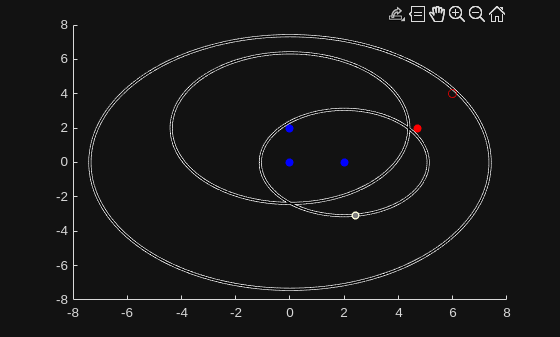

figure;


scatter(posVec(:,1), posVec(:,2),'b', 'filled');
hold on;   
centers = posVec(:, :);        % 3×2 array of [x y]
radii   = distVec(:);        % 3×1 vector of radiifile:///home/jordan/Documents/Xbee - Copy/xBeeData_2025_4_25_18_1_6.8969.csv
viscircles(centers, radii, 'EdgeColor','k','LineWidth',1.2);

scatter(position(1), position(2),'r', 'filled');
scatter(truePos(1), truePos(2), 'red', 'o')